# Part 1

Now let's solve a simple boundary-value problem:

Let $\Omega = (0, 1)$. 


$$\frac{d^2 u}{d x^2} + f = 0 \\
u(1) = g \\
\frac{d u}{d x}(0) = h
$$


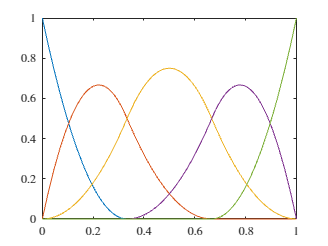

clear
close all

x = sym( "x", "real" );
degree = [2, 2, 2];
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 1 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x );

figure
fplot( basis.Basis, domain )


f = sin( pi * x )^2

$$f = {\sin\left(\pi \,x\right)}^{2}$$

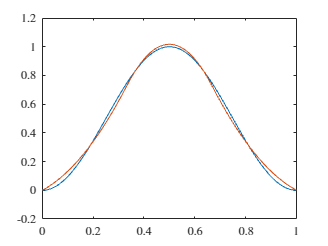

boundary_tol = 1e-6;
penalty = 1e12;
u = ScalarProjection( f, basis, boundary_tol, penalty );

figure
hold on
fplot( f, domain )
fplot( u, domain )

clear
close all

x = sym( "x", "real" );
f(x) = x^0; %piecewise( ( -0.25 <= x ) & ( x <= 0.25 ), 1, 0 );
g = 0;
h = 0;
boundary_tol = 1e-6;
penalty = 1e12;

degree = [2, 2, 2];
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 1 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x );

[u, M, F, N, d] = HeatEquation( basis, f, g, h, boundary_tol, penalty );

exactSolution = ExactHeatSolution( f, g, h, domain );
l2_error = ComputeL2Error( exactSolution.U, simplify( u ), domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.0000008371033404680469$$

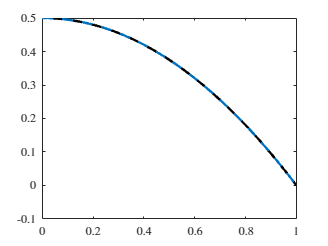


figure
hold on
fplot( exactSolution.U, domain, Color="k", LineWidth=2 )
fplot( u, domain, SeriesIndex=1, LineWidth=2, LineStyle="--" )

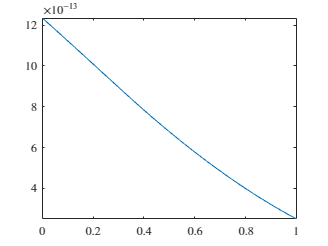


figure
fplot( ( exactSolution.U - u )^2, domain )

clear
close all

x = sym( "x", "real" );
domain = [0, 1];

E = 1e3;
I = 1/12;
f(x) = 1e-3 * x ^ 1;
M = 2e-2;
Q = 5e-3;

exactSolution = ExactBernoulliEulerBeamSolution( E, I, f, M, Q, domain );

degree = [4, 4, 4];
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 3 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x );

displacement_constraint = 0;
slope_constraint = 0;
boundary_tol = 1e-6;
penalty = 1e12;
approxSolution = BernoulliEulerBeamEquation( basis, E, I, displacement_constraint, slope_constraint, f, M, Q, boundary_tol, penalty );
l2_error = ComputeL2Error( exactSolution.U, simplify( approxSolution ), domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.00000001800966005683602$$

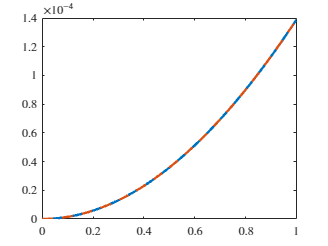


figure
hold on
fplot( exactSolution.U, domain, LineStyle="-", LineWidth=2 )
fplot( approxSolution, domain, LineStyle="--", LineWidth=2 )

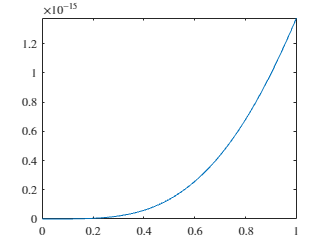


figure
fplot( ( exactSolution.U - approxSolution )^2, domain )

clear
close all

x = sym( "x", "real" );
domain = [0, 1];

f(x) = 1*x^0;
a = 0;
b = 0;
c = 0;

exactSolution = ExactThirdOrderSolution( f, a, b, c, domain )

exactSolution = struct with fields:
         f: [1×1 symfun]
       eqn: [1×1 symfun]
      cond: [u(0) == 0    subs(diff(u(x), x), x, 0) == 0    subs(diff(u(x), x, x), x, 0) == 0]
    domain: [0 1]
         U: [1×1 symfun]



boundary_tol = 1e-6;
penalty = 1e12;

degree = [3, 3, 3];
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 2 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x );

approxSolution = ThirdOrderPDE( basis, f, a, b, c, boundary_tol, penalty );

l2_error = ComputeL2Error( exactSolution.U, simplify( approxSolution ), domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.0000001238269870886549$$

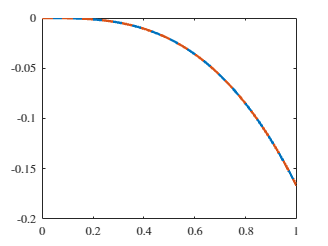


figure
hold on
fplot( exactSolution.U, domain, LineStyle="-", LineWidth=2 )
fplot( approxSolution, domain, LineStyle="--", LineWidth=2 )

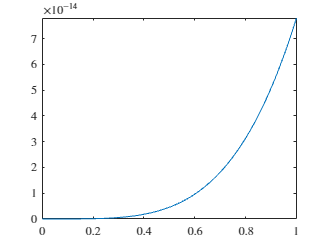


figure
fplot( ( exactSolution.U - approxSolution )^2, domain )